## 🧩 Case Study: Air Quality Prediction (Simple Model)

**Goal: **Predict CO concentration (mg/m³) using readings from 5 metal oxide sensors.

1️⃣ Load and Prepare the Data

Assuming you have the dataset file, e.g.,

AirQualityUCI.csv (available from UCI Repository).


% === Step 1: Load dataset ===
data = readtable('AirQualityUCI.csv');


% Inspect column names
data.Properties.VariableNames

ans = 1×15 cell array
    {'Date'}    {'Time'}    {'CO_GT_'}    {'PT08_S1_CO_'}    {'NMHC_GT_'}    {'C6H6_GT_'}    {'PT08_S2_NMHC_'}    {'NOx_GT_'}    {'PT08_S3_NOx_'}    {'NO2_GT_'}    {'PT08_S4_NO2_'}    {'PT08_S5_O3_'}    {'T'}    {'RH'}    {'AH'}


🧩 Step 2: Clean Missing Values (-200)

% Replace -200 with NaN for all numeric variables
vars = data.Properties.VariableNames;

for i = 1:numel(vars)
    if isnumeric(data.(vars{i}))
        data.(vars{i})(data.(vars{i}) == -200) = NaN;
    end
end

% Remove rows with missing numeric data
data = rmmissing(data);

% Inspect columns
head(data)

       Date         Time      CO_GT_    PT08_S1_CO_    NMHC_GT_    C6H6_GT_    PT08_S2_NMHC_    NOx_GT_    PT08_S3_NOx_    NO2_GT_    PT08_S4_NO2_    PT08_S5_O3_     T       RH       AH  
    __________    ________    ______    ___________    ________    ________    _____________    _______    ____________    _______    ____________    ___________    ____    ____    ______

    10/03/2004    18:00:00     2.6         1360          150         11.9          1046           166          10

2️⃣ Select Features (X) and Target (Y)

Let's use the 5 metal oxide sensors as features.

% Select only numeric sensor columns (example names from file)
X = data{:, {'PT08_S1_CO_','PT08_S2_NMHC_','PT08_S3_NOx_','PT08_S4_NO2_','PT08_S5_O3_'}};
Y = data.CO_GT_;   % Reference CO concentration (target)

3️⃣ Split Training and Testing Sets

% Split data into train/test
cv = cvpartition(length(Y), 'HoldOut', 0.3);
Xtrain = X(training(cv), :);
Ytrain = Y(training(cv), :);
Xtest  = X(test(cv), :);
Ytest  = Y(test(cv), :);

4️⃣ Train Model

Mdl = fitlm(Xtrain, Ytrain); 		    % Linear Regression
tree = fitrtree(Xtrain, Ytrain); 		% Regression Tree
svmMdl = fitrsvm(Xtrain, Ytrain); 	    % Support Vector Regression

5️⃣ Predict and Evaluate

% Make predictions
Ypred1 = predict(Mdl, Xtest);
Ypred2 = predict(tree, Xtest);
Ypred3 = predict(svmMdl, Xtest);

% Evaluate performance
rmse1 = sqrt(mean((Ypred1 - Ytest).^2));

rmse1 = 0.3340

rmse2 = sqrt(mean((Ypred2 - Ytest).^2));

rmse2 = 0.3845

rmse3 = sqrt(mean((Ypred3 - Ytest).^2));

rmse3 = 1.1917


models = {'Linear Regression'; 'Regression Tree'; 'SVM Regression'};
RMSE = [rmse1; rmse2; rmse3];
T = table(models, RMSE)

T = 3×2 table
           models             RMSE  
    _____________________    _______

    {'Linear Regression'}    0.33398
    {'Regression Tree'  }    0.38453
    {'SVM Regression'   }     1.1917


6️⃣ Visualize Results

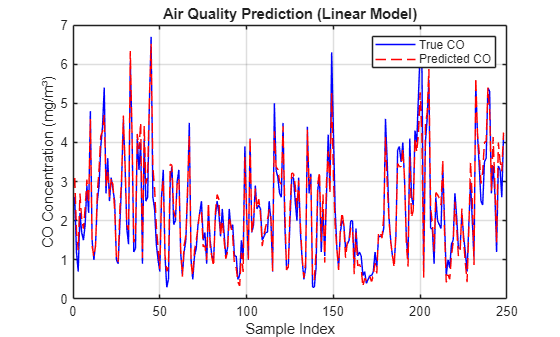

figure;
plot(Ytest, 'b-', 'DisplayName', 'True CO'); hold on;
plot(Ypred1, 'r--', 'DisplayName', 'Predicted CO');
xlabel('Sample Index'); ylabel('CO Concentration (mg/m³)');
title('Air Quality Prediction (Linear Model)');
legend; grid on;